dataProviderFile = fullfile(fileparts(SBTiroot), 'examples', "data/data_provider_example.xlsx");
provider = SBTi.data.ExcelProvider(dataProviderFile)

provider =   ExcelProvider with properties:

    data: "C:\Users\ebenetce\MATLAB\SBTi_MATLAB\examples\data\data_provider_example.xlsx"
       c: [1×1 SBTi.configs.ColumnsConfig]


examplePortfoliofile = fullfile(fileparts(SBTiroot), 'examples', "data/example_portfolio.csv");
opts = detectImportOptions(examplePortfoliofile);
opts.Encoding = 'ISO-8859-15';
opts = setvartype(opts, 'engagement_target', 'logical');
portfolio = readtable(examplePortfoliofile, opts);
portfolio.engagement_target = logical(portfolio.engagement_target);
head(portfolio)

ans = 8×6 table
     company_name        company_id         company_isin       weights     investment_value    engagement_target
    ______________    ________________    ________________    _________    ________________    _________________

    {'Company AG'}    {'US0079031078'}    {'US0079031078'}    {'6.36%'}        3.5e+07               true       
    {'Company AH'}    {'US00724F1012'}    {'US00724F1012'}    {'1.82%'}          1e+07               false      
    {'Company AI'}    {'FR0000125338'}    {'FR0000125338'}    {'1.82%'}          1e+07               false      
    {'Company AJ'}    {'US17275R1023'}    {'US17275R1023'}    {'1.82%'}          1e+07               false      
    {'Company AK'}    {'CH0198251305'}    {'CH0198251305'}    {'1.82%'}          1e+07               

companies = SBTi.utils.table_to_portfolio(portfolio)

companies =   16×1 PortfolioCompany array with properties:

    company_name
    company_id
    company_isin
    investment_value
    engagement_target
    user_fields


import SBTi.interfaces.*
time_frames = ETimeFrames.MID

time_frames = "mid"

scopes = [EScope.S1S2, EScope.S1S2S3]

scopes = 1×2 string array
    "S1+S2"    "S1+S2+S3"


fallback_score = 3.2

fallback_score = 3.2000

temperature_score = SBTi.TemperatureScore( time_frames=time_frames, scopes=scopes, fallback_score=fallback_score)

temperature_score =   TemperatureScore with properties:

                 model: 4
              scenario: []
        fallback_score: 3.2000
           time_frames: "mid"
                scopes: ["S1+S2"    "S1+S2+S3"]
    aggregation_method: WATS
              grouping: []
               mapping: [9×4 table]
      regression_model: [42×7 table]
                     c: [1×1 SBTi.configs.TemperatureScoreConfig]


amended_portfolio = temperature_score.calculate(data_providers=provider, portfolio=companies);
head(amended_portfolio)

ans = 8×46 table
      company_id      time_frame     scope     achieved_reduction    base_year    base_year_ghg_s1    base_year_ghg_s2    base_year_ghg_s3    coverage_s1    coverage_s2    coverage_s3    end_year    intensity_metric    reduction_ambition    start_year    target_type    company_name      isic        ghg_s1s2       ghg_s3        country           region                  sector             industry_level_1    industry_level_2    industry_level_3    industry_level_4    company_revenue    company_ma

temperature_score.aggregation_method = SBTi.PortfolioAggregationMethod.ROTS;
aggregated_portfolio = temperature_score.aggregate_scores(amended_portfolio)

aggregated_portfolio =   ScoreAggregations with properties:

    short: [0×1 SBTi.interfaces.ScoreAggregationScopes]
      mid: [1×1 SBTi.interfaces.ScoreAggregationScopes]
     long: [0×1 SBTi.interfaces.ScoreAggregationScopes]


print_aggregations(aggregated_portfolio)

 Timeframe      Scope    Temp score
       mid       S1S2       3.12
       mid     S1S2S3       2.73


portfolio_coverage_tvp = SBTi.PortfolioCoverageTVP();
coverage = portfolio_coverage_tvp.get_portfolio_coverage(amended_portfolio, temperature_score.aggregation_method);
fprintf("Part of portfolio with climate targets is %.2f%%",coverage)

Part of portfolio with climate targets is 24.11%

grouping = ["sector", "region"];
temperature_score = SBTi.TemperatureScore( time_frames=time_frames, scopes=scopes, grouping=grouping );
grouped_portfolio = temperature_score.calculate(data_providers=provider, portfolio=companies)

grouped_portfolio = 98×46 table
      company_id      time_frame     scope     achieved_reduction    base_year    base_year_ghg_s1    base_year_ghg_s2    base_year_ghg_s3    coverage_s1    coverage_s2    coverage_s3    end_year    intensity_metric    reduction_ambition    start_year    target_type    company_name      isic        ghg_s1s2       ghg_s3         country           region                  sector             industry_level_1    industry_level_2    industry_level_3    industry_level_4    company_revenue    <s

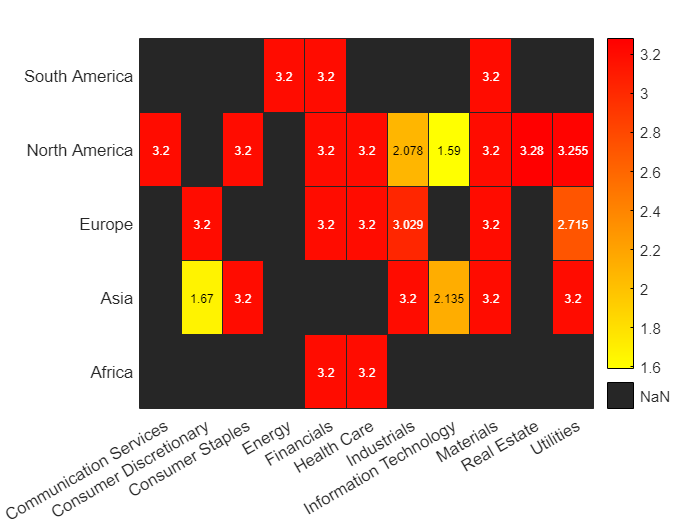

grouped_aggregations = temperature_score.aggregate_scores(grouped_portfolio);
analysis_parameters = {ETimeFrames.MID, EScope.S1S2, grouping};
plot_grouped_heatmap(grouped_aggregations, SBTi.interfaces.ETimeFrames.MID, SBTi.interfaces.EScope.S1S2, grouping);

region =  "Asia";
sector = "Industrials"

sector = "Industrials"

group = sector + '-' + region;
group_contributions = get_contributions_per_group(grouped_aggregations, analysis_parameters, group)

group_contributions = 3×5 table
          group           company_name      company_id      temperature_score    contribution_relative
    __________________    ____________    ______________    _________________    _____________________

    "Industrials-Asia"    "Company G"     "CN0000000007"           3.2                  33.333        
    "Industrials-Asia"    "Company AS"    "JP3401400001"           3.2                  33.333        
    "Industrials-Asia"    "Company AE"    "TH0000000031"           3.2                  33.333        


time_frames = SBTi.interfaces.ETimeFrames.MID;
scopes = SBTi.interfaces.EScope.S1S2;
grouping = "sector";
analysis_parameters = {time_frames, scopes, grouping};
temperature_score = SBTi.TemperatureScore(time_frames=time_frames, scopes=scopes, grouping=grouping);
amended_portfolio = temperature_score.calculate(data_providers=provider, portfolio=companies);
aggregated_portfolio = temperature_score.aggregate_scores(amended_portfolio)

aggregated_portfolio =   ScoreAggregations with properties:

    short: [0×1 SBTi.interfaces.ScoreAggregationScopes]
      mid: [1×1 SBTi.interfaces.ScoreAggregationScopes]
     long: [0×1 SBTi.interfaces.ScoreAggregationScopes]


company_contributions = collect_company_contributions(aggregated_portfolio, amended_portfolio, analysis_parameters)

company_contributions = 49×10 table
    company_name    contribution    temperature_score    company_name_right      company_id      company_market_cap    investment_value             sector             portfolio_percentage    ownership_percentage
    ____________    ____________    _________________    __________________    ______________    __________________    ________________    ________________________    ____________________    ____________________

    "Company N"        8.7097              3.2              "Company N"        "FR0000000014"        2.2741e+10            4.3e+07         "Health Care"                      7.8182                  0

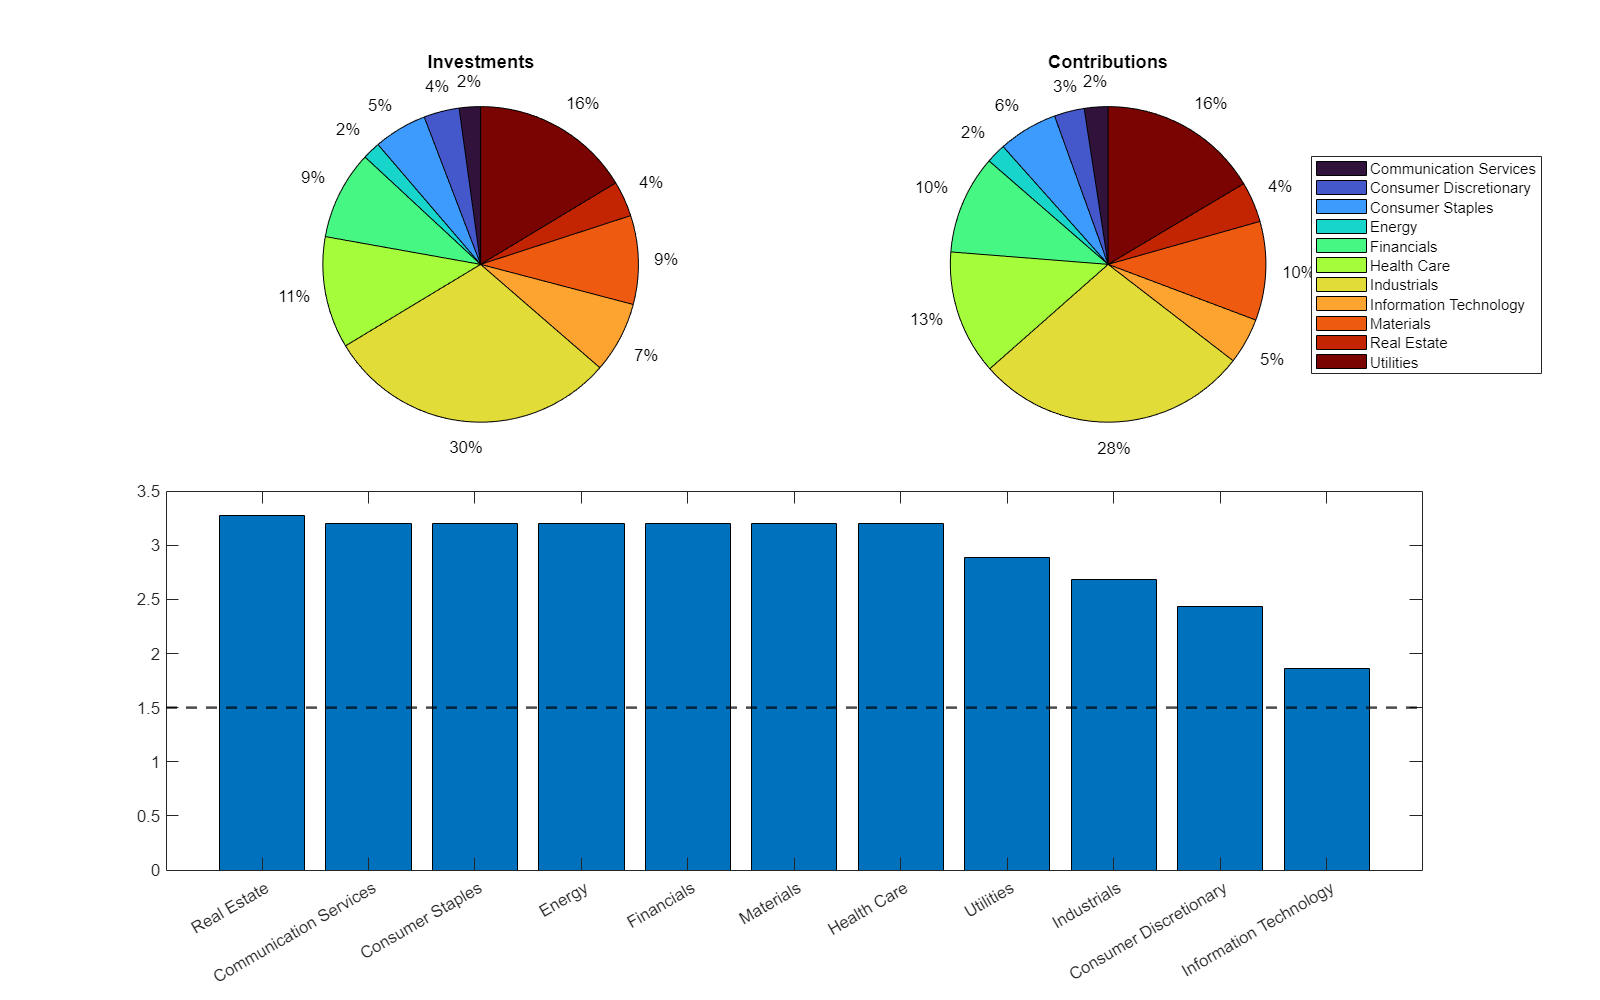

plot_grouped_statistics(aggregated_portfolio, company_contributions, analysis_parameters)

sector_contributions = company_contributions(:,["company_name", "company_id", "sector", "contribution", "temperature_score", "ownership_percentage", "portfolio_percentage"]);
sector_contributions(sector_contributions.sector == 'Health Care', :)

ans = 3×7 table
    company_name      company_id         sector        contribution    temperature_score    ownership_percentage    portfolio_percentage
    ____________    ______________    _____________    ____________    _________________    ____________________    ____________________

    "Company N"     "FR0000000014"    "Health Care"       8.7097              3.2                  0.18909                 7.8182       
    "Company AD"    "KE0000000030"    "Health Care"       2.0255              3.2                 0.013243                 1.8182       
    "Company AL"    "US1266501006"    "Health Care"       2.0255              3.2                 0.011175                 1.8182       


head(company_contributions(:,["company_name", "company_id", "contribution", "temperature_score", "ownership_percentage", "portfolio_percentage"]))

ans = 8×6 table
    company_name      company_id      contribution    temperature_score    ownership_percentage    portfolio_percentage
    ____________    ______________    ____________    _________________    ____________________    ____________________

    "Company N"     "FR0000000014"       8.7097              3.2                  0.18909                 7.8182       
    "Company AG"    "US0079031078"       4.4973             2.03                  0.33445                 6.3636       
    "Company Q"     "CA0000000017"       2.4306              3.2                   4.8111                 2.1818       
    "Company AO"    "TW0002308004"       2.4243             3.83                 0.014135                 1.8182       
    "Company U"     "US0000000021"       2.1268            

scenario = SBTi.Scenario();
scenario.scenario_type = SBTi.ScenarioType.HIGHEST_CONTRIBUTORS_APPROVED;
scenario.engagement_type = SBTi.EngagementType.SET_TARGETS;
% These two lines do not do anything, 
% scenario.aggregation_method = SBTi.PortfolioAggregationMethod.WATS;
% scenario.grouping = "sector";


scenario_portfolio = portfolio;
scenario_portfolio{scenario_portfolio.company_id == "CA0000000017", 'engagement_target'} = true;
scenario_portfolio{scenario_portfolio.company_id == "FR0000120644", 'engagement_target'} = true;

scenario_companies = SBTi.interfaces.PortfolioCompany(scenario_portfolio);
scenario_data = SBTi.utils.get_data(provider, scenario_companies);
temperature_score.scenario = scenario;
scenario_companies = SBTi.utils.table_to_portfolio(scenario_portfolio);
scenario_scores = temperature_score.calculate(data_providers=provider, portfolio=scenario_companies);
scenario_aggregated = temperature_score.aggregate_scores(scenario_scores);

print_scenario_gain(aggregated_portfolio, scenario_aggregated)

Actual portfolio temperature score
 Timeframe      Scope    Temp score
       mid       S1S2       2.87

Scenario portfolio temperature score
 Timeframe      Scope    Temp score
       mid       S1S2       2.71


Actual temperature scores

print_grouped_scores(aggregated_portfolio)

                         Temp score
mid - S1S2
Communication Services     3.20
Consumer Discretionary     2.44
Consumer Staples           3.20
Energy                     3.20
Financials                 3.20
Health Care                3.20
Industrials                2.69
Information Technology     1.86
Materials                  3.20
Real Estate                3.28
Utilities                  2.89


Scenario temperature scores

print_grouped_scores(scenario_aggregated)

                         Temp score
mid - S1S2
Communication Services     2.00
Consumer Discretionary     2.44
Consumer Staples           3.20
Energy                     2.00
Financials                 3.20
Health Care                3.20
Industrials                2.53
Information Technology     1.86
Materials                  3.20
Real Estate                2.60
Utilities                  2.62


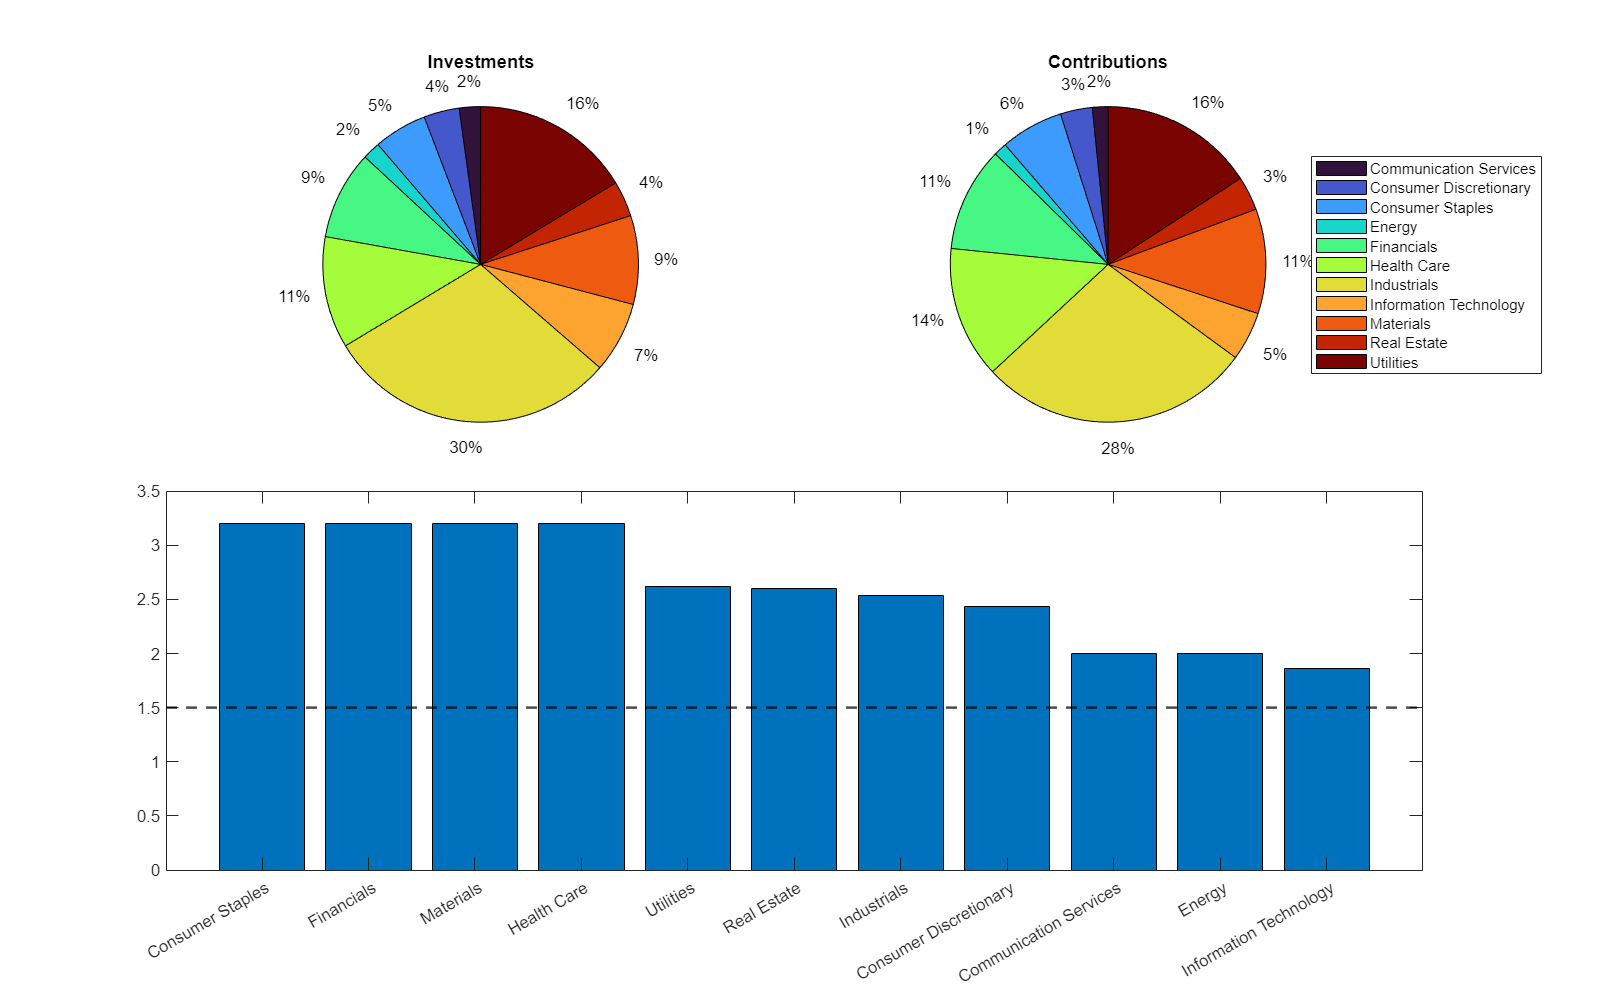

scenario_contributions = collect_company_contributions(scenario_aggregated, scenario_scores, analysis_parameters);

scenario_aggregated;
scenario_contributions;
analysis_parameters;
plot_grouped_statistics(scenario_aggregated, scenario_contributions, analysis_parameters)

scenario_contributions.temperature_score_change = scenario_contributions.temperature_score - company_contributions.temperature_score;
scenario_contributions.contribution_change = scenario_contributions.contribution - company_contributions.contribution;
largest_reductions = scenario_contributions(scenario_contributions.temperature_score_change ~= 0.0,:);